This live script provides ex

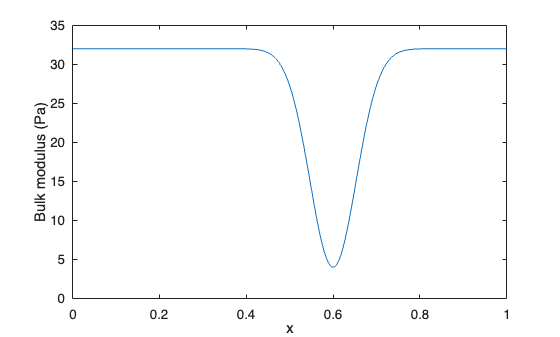

clear
close all
clc

% Grids and grid spaces
domain_x = [0,1]; Nx=401;
grid_primal = Grid1DUnifPrimal([0,1],401);
grid_dual   = Grid1DUnifDual(grid_primal);

gsp_P = GridSpace1D(grid_primal);
gsp_V = GridSpace1D(grid_dual);

% Medium
medium = AcousticMedium1D.gaussian( ...
    BetaInside=0.25, ...
    BetaOutside=0.5, ...
    KappaInside=4, ...
    KappaOutside=32, ...
    Center=0.6, ...
    Width=0.075);
[kappa,beta,wspeed,cMax] = sampleMedium1D(gsp_P,medium);

kappa.plot;

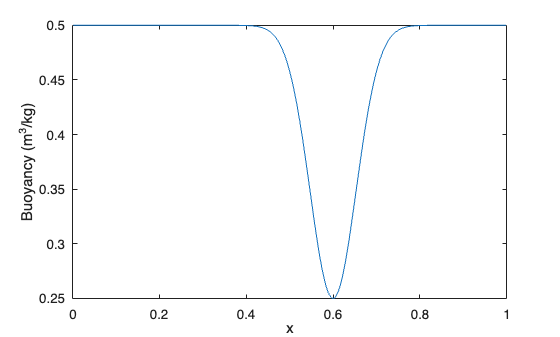

beta.plot;

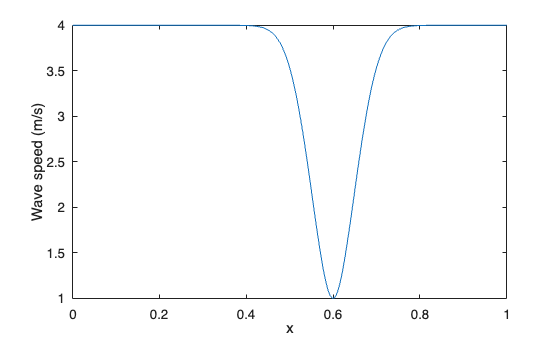

wspeed.plot;


% Time grid
domain_t = [0,1];
CFL = 0.9;
dt = CFL*(6/7)*gsp_P.h/cMax;
Nt = ceil(diff(domain_t)/dt)+1;
dt = diff(domain_t)/(Nt-1); %recomputing dt to ensure time length is divisible by dt
times = domain_t(1):dt:domain_t(2);

% Define two multipole terms
% An order-zero pressure monopole at x=0.35.
monopole = MultipoleTerm1D( ...
    0.33,0,@(t) exp(-((t-0.10)/0.025).^2), ...
    Amplitude=1,TargetField="pressure");

% A first derivative of delta at x=0.65. This produces a dipole-like
% signed spatial source. Its time pulse is delayed relative to the first.
dipole = MultipoleTerm1D( ...
    0.8,1,@(t) exp(-((t-0.18)/0.035).^2), ...
    Amplitude=0.04,TargetField="pressure");

% Construct and discretize the multipole source
mps = MultipoleSeries1D( ...
    [monopole,dipole],ApproximationOrder=4);
source = mps.discretize(gsp_P,gsp_V);

% Initializing PML
pml = PML1D( ...
    WidthLeft=0.2, ...
    WidthRight=0, ...
    ReflectionCoefficient=1e-6, ...
    PolynomialDegree=3);

% Output grid and times
gsp_out   = GridSpace1D(Grid1DUnifPrimal(domain_x,101));
times_out = linspace(domain_t(1),domain_t(2),81);

% Initial conditions
p0 = @(x) zeros(size(x));
v0 = @(x) zeros(size(x));

% Initialize solver
solver = AcousticSolver1D_PML( ...
    gsp_P,times, ...
    gsp_out,times_out, ...
    medium, pml, ...
    SpatialOrder=4);

% Run solver
[P,V] = solver.solve(p0,v0,Source=source);

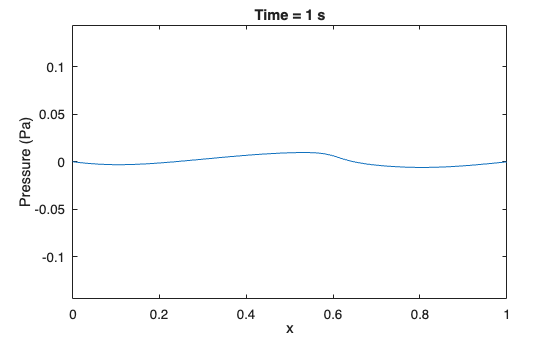

P.animate(FramePause=0.03);

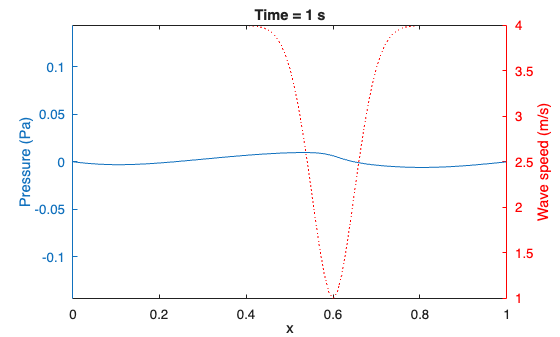

P.animateMedBack(medium);